odor_panel_filename='odor panel.txt';

T = readtable('hallem_set_complete.csv', 'readRowNames', true);

T.Var25=[];
T.sum=[];
odor_panel=table2cell(readtable('odor_panel.txt', 'ReadVariableNames', false, 'delimiter', '\n'))

odor_panel = 5×1 cell array
    '1-hexanol'
    '1-pentanol'
    'ethyl propionate'
    'methyl salicylate'
    'geranyl acetate'


odor_panel(4)=[];
pheremone_receptors=table2cell(readtable('pheremone_receptors.txt', 'ReadVariableNames', false, 'delimiter', '\n'))

pheremone_receptors = 4×1 cell array
    'x33b'
    'x47b'
    'x65a'
    'x88a'



T_no_pheremones=T;
T_no_pheremones(:, pheremone_receptors)=[];


ORNc=table2array(T(:,1:24));

%plot ORN heatmap
s=sum(ORNc,2)

s =    131
   -62
    11
   492
   742
   496
   -26
   -34
    86
   140


[A, I]=sort(s, 'ascend');
ORNc_sorted=ORNc(I,:);



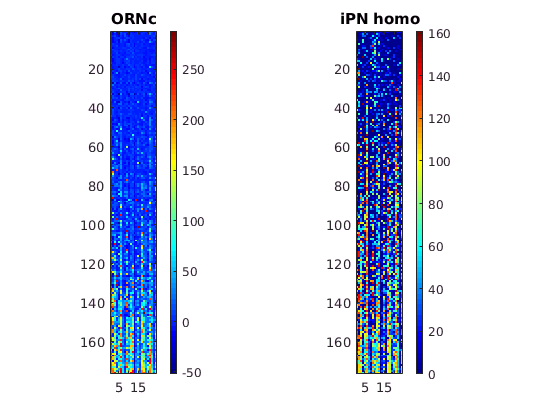


[iPN_homo] = PNtransform(ORNc);
s2=sum(iPN_homo,2);
[B,I2]=sort(s2, 'ascend');

figure
subplot(1,2,1)
imagesc(ORNc_sorted),colormap(jet), colorbar, axis image
title('ORNc')
subplot(1,2,2)
imagesc(iPN_homo(I2,:)), colormap(jet), colorbar, axis image
title('iPN homo')

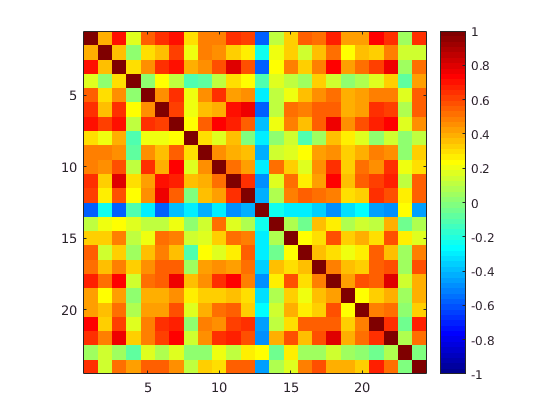


R_ornc=corrcoef(ORNc);
figure('Name','ORNc correlation matrix')
imagesc(R_ornc, [-1 1]), colormap(jet), colorbar, axis image

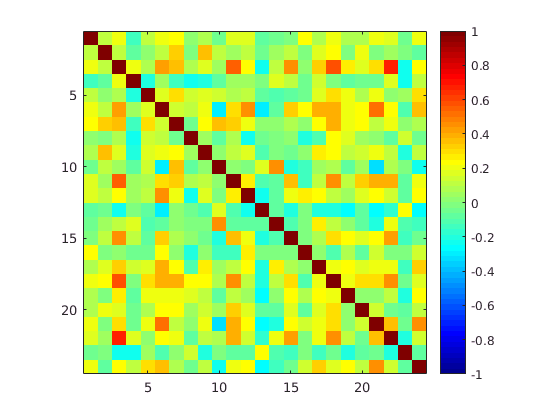


R_PN=corrcoef(iPN_homo);
figure('Name','PN correlation matrix')
imagesc(R_PN, [-1 1]), colormap(jet), colorbar, axis image

## ORN odor panel correlation matrix


odor_panel_T=T_no_pheremones(odor_panel,:);
odor_panel_orn=table2array(odor_panel_T)

odor_panel_orn =     40    96   102    10   146    63    51   237   133    73    58    31    35   173   109    58   137   183    64   158
    35   166   160    11    84   179    73   188    77   109    62    44    55   148   126    55    47   169    56    75
    21    85    58    38   -13   188    -5     1     1   168    55    -5    99    11    47    18    44    57    26    41
     2     1    -5    -8     9     1     4    -3   -10    10    -2    -4    37     7    -3   241    -1    -2    -2    81


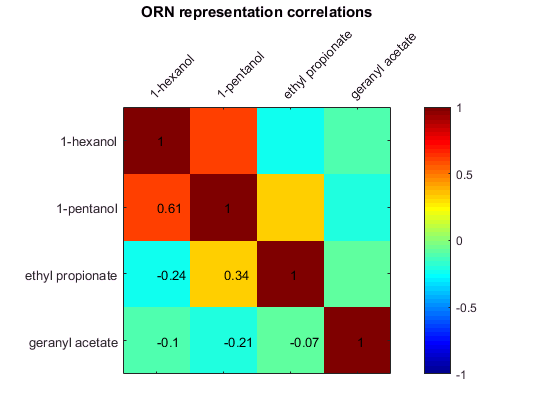

R_odor_orn=corrcoef(odor_panel_orn');
figure, imagesc(R_odor_orn, [-1 1]), colormap(jet), colorbar, axis image
set(gca, 'XTick', 1:5, 'XTickLabel', odor_panel, 'XTickLabelRotation', 45, 'xaxislocation', 'top')
set(gca, 'YTick', 1:5, 'YTickLabel', odor_panel)
title('ORN representation correlations')

axis ij
for i=1:4
   for j=i:4
      text(i,j, num2str(round(R_odor_orn(i,j), 2)))
   end
end

## PN odor panel correlation matrix

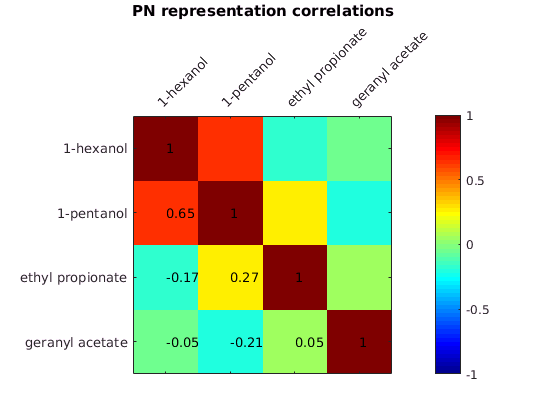


odor_panel_pn=PNtransform(odor_panel_orn);
R_odor_pn=corrcoef(odor_panel_pn');
figure, imagesc(R_odor_pn, [-1 1]), colormap(jet), colorbar, axis image
set(gca, 'XTick', 1:5, 'XTickLabel', odor_panel, 'XTickLabelRotation', 45, 'xaxislocation', 'top')
set(gca, 'YTick', 1:5, 'YTickLabel', odor_panel)
axis ij
for i=1:4
   for j=i:4
      text(i,j, num2str(round(R_odor_pn(i,j), 2)))
   end
end
title('PN representation correlations')

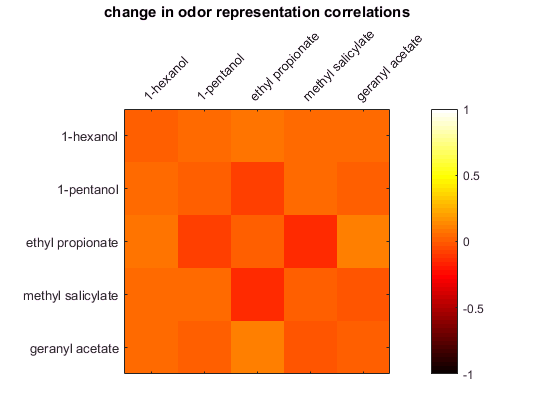

R_odor_diff=R_odor_pn-R_odor_orn;

figure, imagesc(R_odor_diff, [-1 1]), colormap(hot), colorbar, axis image
set(gca, 'XTick', 1:5, 'XTickLabel', odor_panel, 'XTickLabelRotation', 45, 'xaxislocation', 'top')
set(gca, 'YTick', 1:5, 'YTickLabel', odor_panel)
title('change in odor representation correlations')

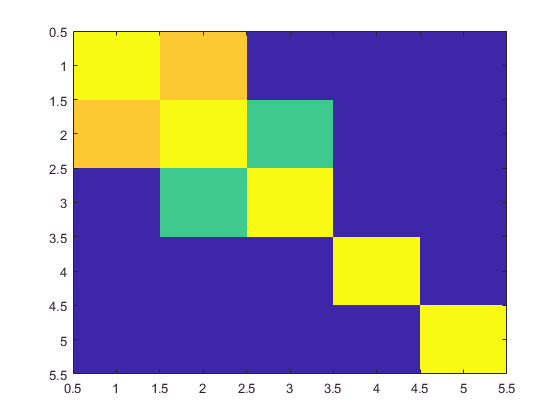


D_orn=nan(4,4);

for i=1:4
   for j=1:4
      D_orn(i,j)=pdist2(odor_panel_pn(i,:), odor_panel_pn(j,:));
   end
end


## save variables

%save('hallem.mat', 'odor_panel', 'odor_panel_orn', 'odor_panel_pn', 'R_odor_diff', 'R_odor_orn', 'R_odor_pn')

orn_no_pheremones=table2array(T_no_pheremones);